clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
t1 = datetime('now');
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,900,'uint8');
labels = zeros(512,512,3,900,'uint8');
for i=3:902
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)

ans =    512   512     3   900


size(labels)

ans =    512   512     3   900


t2 = datetime('now');
dt = between(t1,t2)

dt = calendarDuration
   0h 0m 21.836s



% Init
features_matrix= [];
labelsVec = [];
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

t1 = datetime('now');
t3 = datetime('now');
t4 = datetime('now');
for i=1:size(imgs,4)
    % Read image
    img = imgs(:,:,:,i);
    img_gray = rgb2gray(img);

    % Read Ground Truth Label (Binary Mask)
    label = labels(:,:,:,i);
    % Invert label
    label_= label;
    label_(label_ == 255) = 1;
    label_bin = (label_(:,:,1) + label_(:,:,2) + label_(:,:,3)) > 0;
    label = ones(512,512) - label_bin;

    % Img dimens
    [rows, cols] = size(img_gray);

    % Slide over img with 10x10 window
    for r = 1:window_size:rows-window_size
        for c = 1:window_size:cols-window_size
            % Extract window
            window = img_gray(r:r+window_size-1, c:c+window_size-1);
            label_window = label(r:r+window_size-1, c:c+window_size-1);
            
            % Compute GLCM features
            glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
            stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'}); 
            % High contrast is rough terrain (landlside)
            % Low E is more randomness (lanslide distrutpins)
            % High homogeneirty is uniform areas (vegetation or stable land)

            % Store features
            features = [mean(stats.Contrast), mean(stats.Correlation), ...
                mean(stats.Energy), mean(stats.Homogeneity),];
            features_matrix = [features_matrix; features]; % Append row
        
            % Assing label - if 10% of pix in label is 1, mark as landlside
            if sum(label_window,'all') >= (window_size*window_size/10)
                lbl = 1; % Landlside present
            else
                lbl = 0; % No landslide
            end
            labelsVec = [labelsVec; lbl]; % Append label
        end
    end 
    if i == 50 || i == 100 || i == 150 || i == 200 || i == 250 || i == 300 || i == 350 || i == 400 || i == 450 || i == 500 || i == 550 || i == 600 || i == 650 || i == 700 || i == 750 || i == 800 || i == 850 || i == 900
        i
        t4 = datetime('now');
        dt = between(t3,t4)
        t3 = datetime('now');
    end
end

i = 50

dt = calendarDuration
   0h 2m 11s


i = 100

dt = calendarDuration
   0h 5m 35.344s


i = 150

dt = calendarDuration
   1h 51m 12.747s


i = 200

dt = calendarDuration
   0h 34m 46.942s


i = 250

dt = calendarDuration
   0h 29m 30.508s


i = 300

dt = calendarDuration
   0h 24m 43.103s


i = 350

dt = calendarDuration
   14h 3m 44.934s


i = 400

dt = calendarDuration
   0h 35m 13.753s


i = 450

dt = calendarDuration
   1h 6m 1.6361s


i = 500

dt = calendarDuration
   0h 51m 1.1467s


i = 550

dt = calendarDuration
   1h 7m 45.812s


i = 600

dt = calendarDuration
   1h 31m 4.7374s


i = 650

dt = calendarDuration
   0h 54m 26.941s


i = 700

dt = calendarDuration
   0h 56m 11.377s


i = 750

dt = calendarDuration
   0h 59m 47.356s


% Save dataset for training
save('C:/Users/andre/Year5/EE581/Project/Scripts/landslide_features_dataset.mat', 'features_matrix','labelsVec')
disp('Sliding window feature extraction completed and saved.');

%% Now train SVM classifier with localisex feature vectors (classify if 10x10 
% portion of image is landlside via the features)

% Train SVM model
svmModel = fitcsvm(features_matrix, labelsVec, 'KernelFunction','linear'); % Maybe rbf

% Save trained model
save('C:/Users/andre/Year5/EE581/Project/Scripts/svm_landslide_model.mat', 'svmModel');
disp('SVM trained and model saved');
save('C:/Users/andre/Year5/EE581/Project/Scripts/svm_landslide_features.mat', 'features_matrix');
disp('Features saved');
save('C:/Users/andre/Year5/EE581/Project/Scripts/svm_landslide_features_labels.mat', 'labelsVec');
disp('Feature labels saved');
save('C:/Users/andre/Year5/EE581/Project/Scripts/svm_landslide_features_and_labels.mat', 'features_matrix', 'labelsVec');
disp('Features and labels saved');
t2 = datetime('now');
dt = between(t1,t4)

t1 = datetime('now');
load('svm_landslide_features_v4.mat')
load('svm_landslide_features_labels_v4.mat')

% Train SVM model 1722
svmModel = fitcsvm(features_matrix(1:1000000,:), labelsVec(1:1000000,:), 'KernelFunction','linear'); % Maybe rbf 
% 18s->100k, 16m->500k, 17.5m->700k, 44.5m->1M

t2 = datetime('now');
dt = between(t1,t2)

dt = calendarDuration
   0h 44m 37.946s


saveLearnerForCoder(svmModel,'SVMIris');

dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";

t1 = datetime('now');
%% Classify portions of new image
imgs_files=dir(img_directory)

imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files=dir(label_directory)

labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


imgs = zeros(512,512,3,200,'uint8');
labels = zeros(512,512,3,200,'uint8');
for i=903:1102
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-902) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-902) = double(imread(label_directory + labels_files(i).name));
    end
end

% Init
features_matrix= [];
labelsVec = [];
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

t1 = datetime('now');
t3 = datetime('now');
t4 = datetime('now');
accur = zeros(1,size(imgs,4))

accur =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:20%size(imgs,4)
    % Init result mask
    results_mask = zeros(512, 512);
    
    % Read image
    img = imgs(:,:,:,i);
    img_gray = rgb2gray(img);

    % Read Ground Truth Label (Binary Mask)
    label = labels(:,:,:,i);
    % Invert label
    label_= label;
    label_(label_ == 255) = 1;
    label_bin = (label_(:,:,1) + label_(:,:,2) + label_(:,:,3)) > 0;
    label = ones(512,512) - label_bin;
    
    % Img dimens
    [rows, cols] = size(img_gray);
    
    % initialise landlside_mask
    resultMask = zeros(512,512);

    % Slide over img with 10x10 window
    for r = 1:window_size:rows-window_size
        for c = 1:window_size:cols-window_size
            % Extract window
            window = img_gray(r:r+window_size-1, c:c+window_size-1);
            % label_window = label(r:r+window_size-1, c:c+window_size-1); -
            % use to determine how many times it is accurate with landslide
            % region

            % Compute GLCM features
            test_glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
            test_stats = graycoprops(test_glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'}); 
            test_features = [mean(test_stats.Contrast), mean(test_stats.Correlation), ...
                mean(test_stats.Energy), mean(test_stats.Homogeneity),];
            
            % Predict Landlside or not
            predLabel = predict(svmModel, test_features);

            % Store result in mask
            if predLabel == 1
                resultMask(r:r+window_size-1,c:c+window_size-1) = 1; % Mark landlside area
            end
        end
    end
    % % Display results
    % subplot(1,2,1); imshow(img_gray); title('Original Image');
    % subplot(1,2,2); imshow(result_mask, []); title('Predicted Landslide Regions');

    results_mask = imresize(results_mask, [512, 512], 'nearest');
    [x_lbl, y_lbl] = find(label);
    count = 0;
    for k=1:length(x_lbl)
        if(results_mask(x_lbl(k),y_lbl(k))) == 1
            count = count + 1; % Correctly identified landlside - should also do one for the non-landslide
        end
    end
    similarity = count / length(x_lbl) * 100;
    accur(1,i) = similarity;
    imwrite(results_mask,sprintf('C:/Users/andre/Year5/EE581/Project/Datasets/Full_CAS/Hokkaido Iburi-Tobu/Pred_GLCM/Pred%d.jpg',i));
    
    t4 = datetime('now');
    dt = between(t3,t4)
    t3 = datetime('now');
    if i == 5 || i == 10 || i == 15 || i == 20 || i == 25 || i == 30 || i == 35 || i == 40 || i == 45 || i == 50
            i
    end
end

dt = calendarDuration
   0h 0m 27.109s


dt = calendarDuration
   0h 0m 25.86s


dt = calendarDuration
   0h 0m 26.076s


dt = calendarDuration
   0h 0m 27s


dt = calendarDuration
   0h 0m 27.601s


i = 5

dt = calendarDuration
   0h 0m 27.646s


dt = calendarDuration
   0h 0m 32.801s


dt = calendarDuration
   0h 0m 33.768s


dt = calendarDuration
   0h 0m 33.962s


dt = calendarDuration
   0h 0m 31.08s


i = 10

dt = calendarDuration
   0h 0m 30.417s


dt = calendarDuration
   0h 0m 28.196s


dt = calendarDuration
   0h 0m 28.619s


dt = calendarDuration
   0h 0m 27.124s


dt = calendarDuration
   0h 0m 26.746s


i = 15

dt = calendarDuration
   0h 0m 31.326s


dt = calendarDuration
   0h 0m 30.981s


dt = calendarDuration
   0h 0m 33.172s


dt = calendarDuration
   0h 0m 32.943s


dt = calendarDuration
   0h 0m 35.327s


i = 20

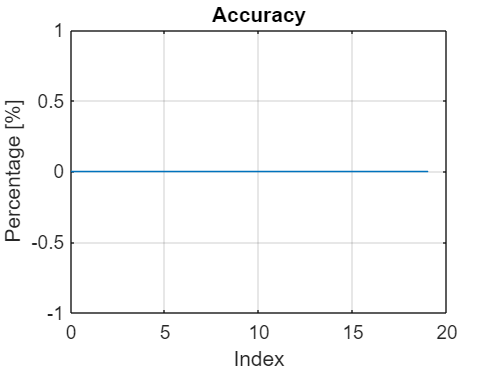

figure; 
plot(0:20-1,accur(1:20));    
xlabel('Index');
ylabel('Percentage [%]');
title('Accuracy')
grid on;

t2 = datetime('now');
dt = between(t1,t2)